# **Running imaging pipeline (cnmf segmentation)**

This live scripts introduce how to work with an existing data pipeline, we will cover the following topics:

- Quick glance on imaging data

- Imaging schema structure

- Example on running an imaging session through the pipeline

## Quick glance on imaging data

Data taken from Sue Ann Koay imaging data: 

**subject_fullname**: koay_k53 **session_date**: 2016-06-23

(You can run "play_imaging_video" to check original data)

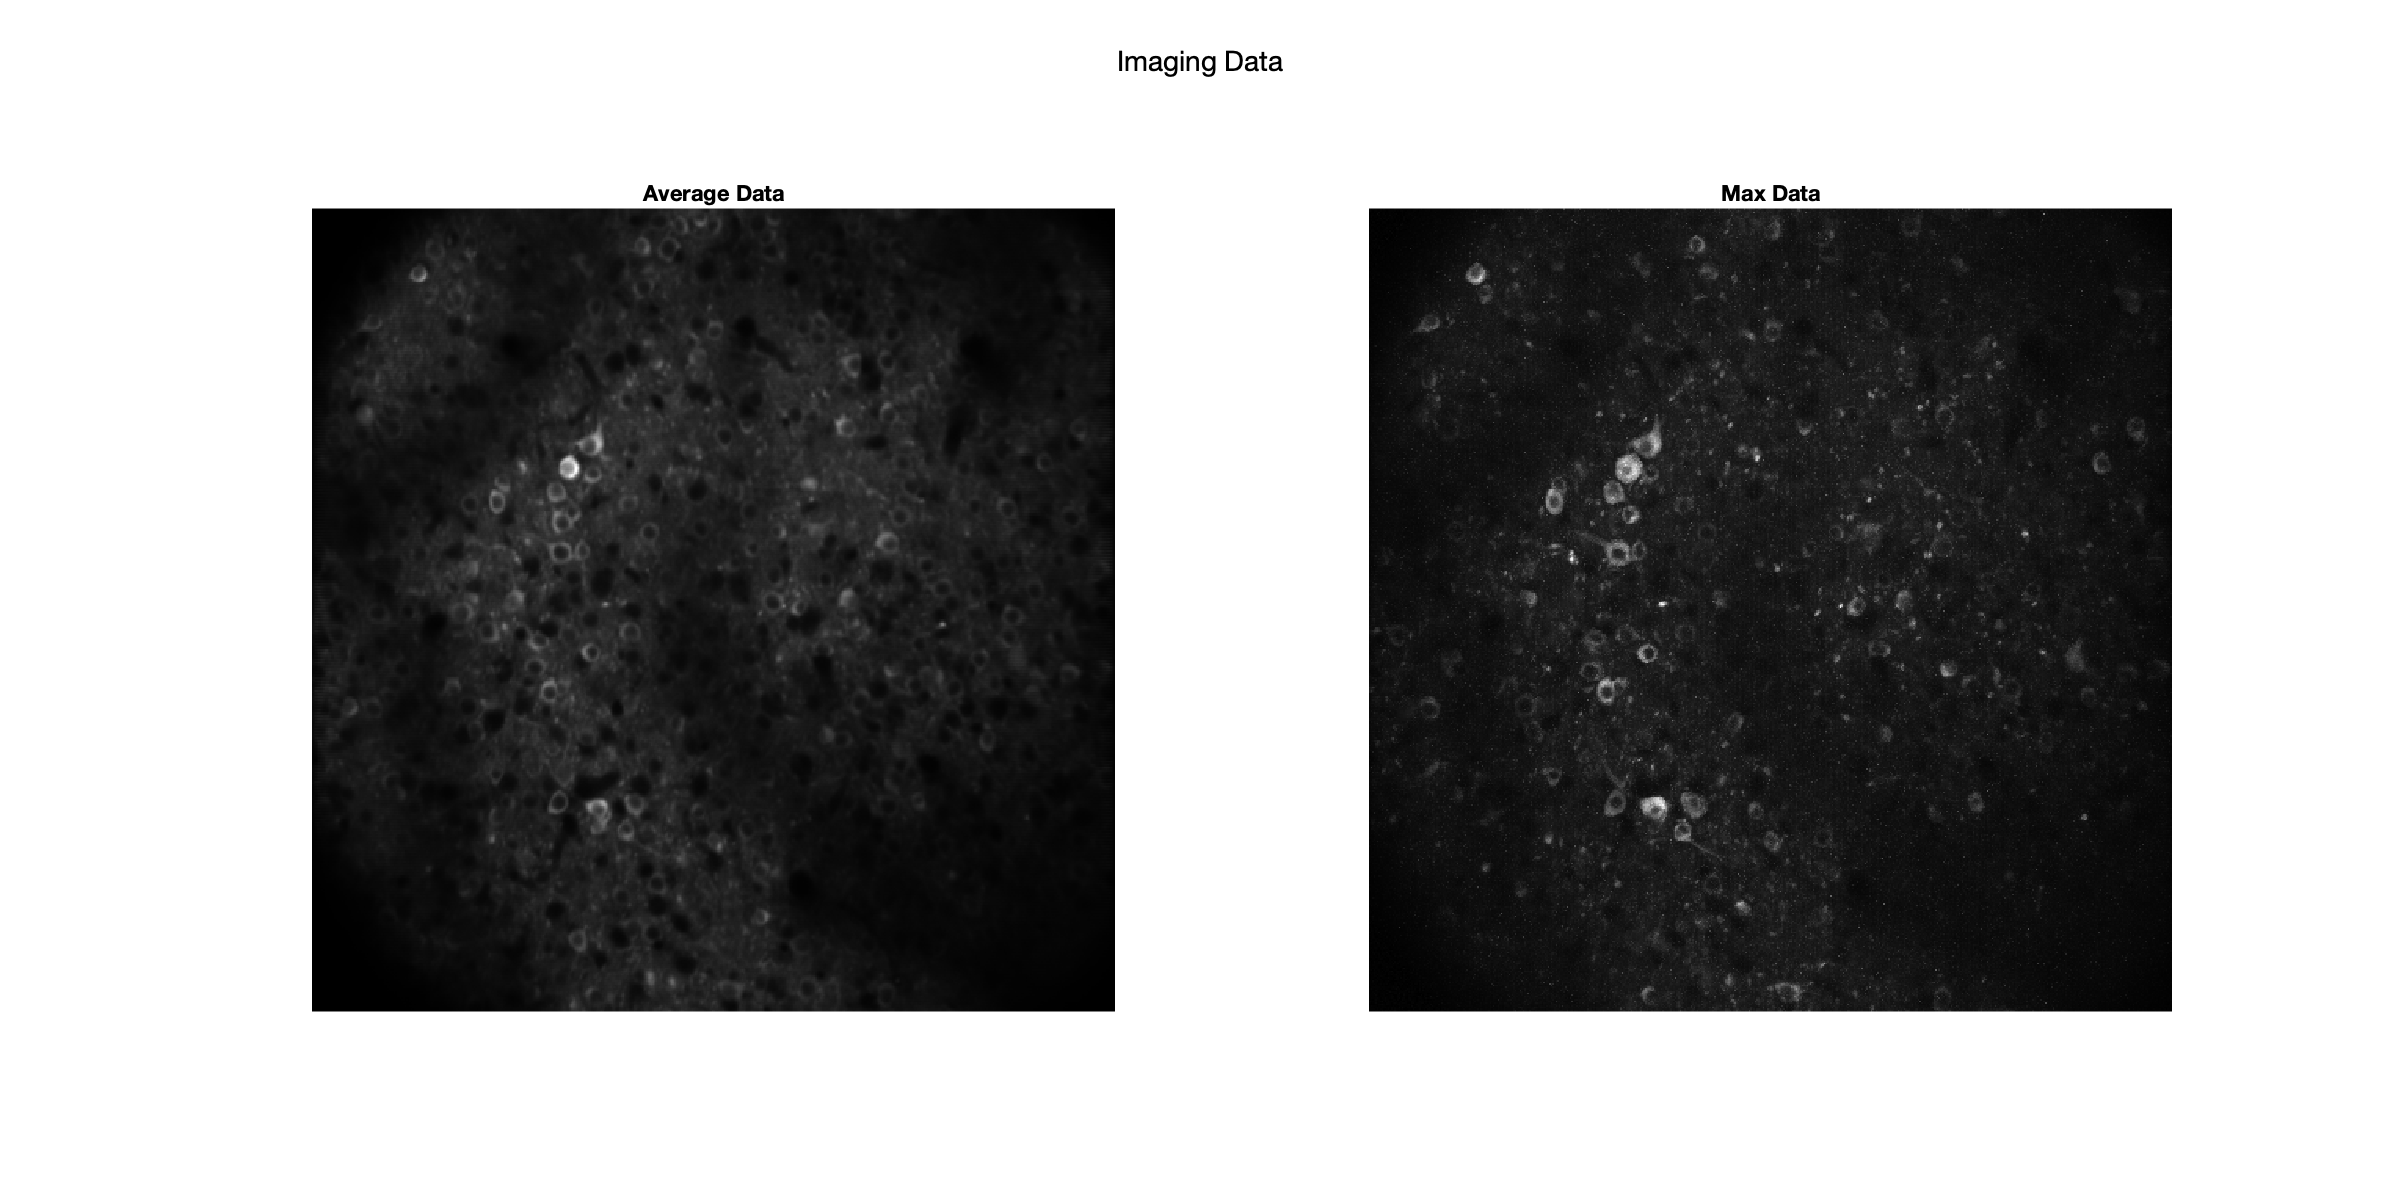

clear livescript
data_dir = fullfile(fileparts(matlab.desktop.editor.getActiveFilename), 'data');
sample_imaging_mean = imread(fullfile(data_dir, 'mean_imaging_session.png'));
sample_imaging_max = imread(fullfile(data_dir, 'max_imaging_session.png'));
set(gcf,'position',[0,0,1200,500])
subplot(1,2,1)
imshow(sample_imaging_mean)
title('Average Data')
subplot(1,2,2)
imshow(sample_imaging_max)
title('Max Data')
suptitle('Imaging Data')

## Imaging schema structure (part 1)

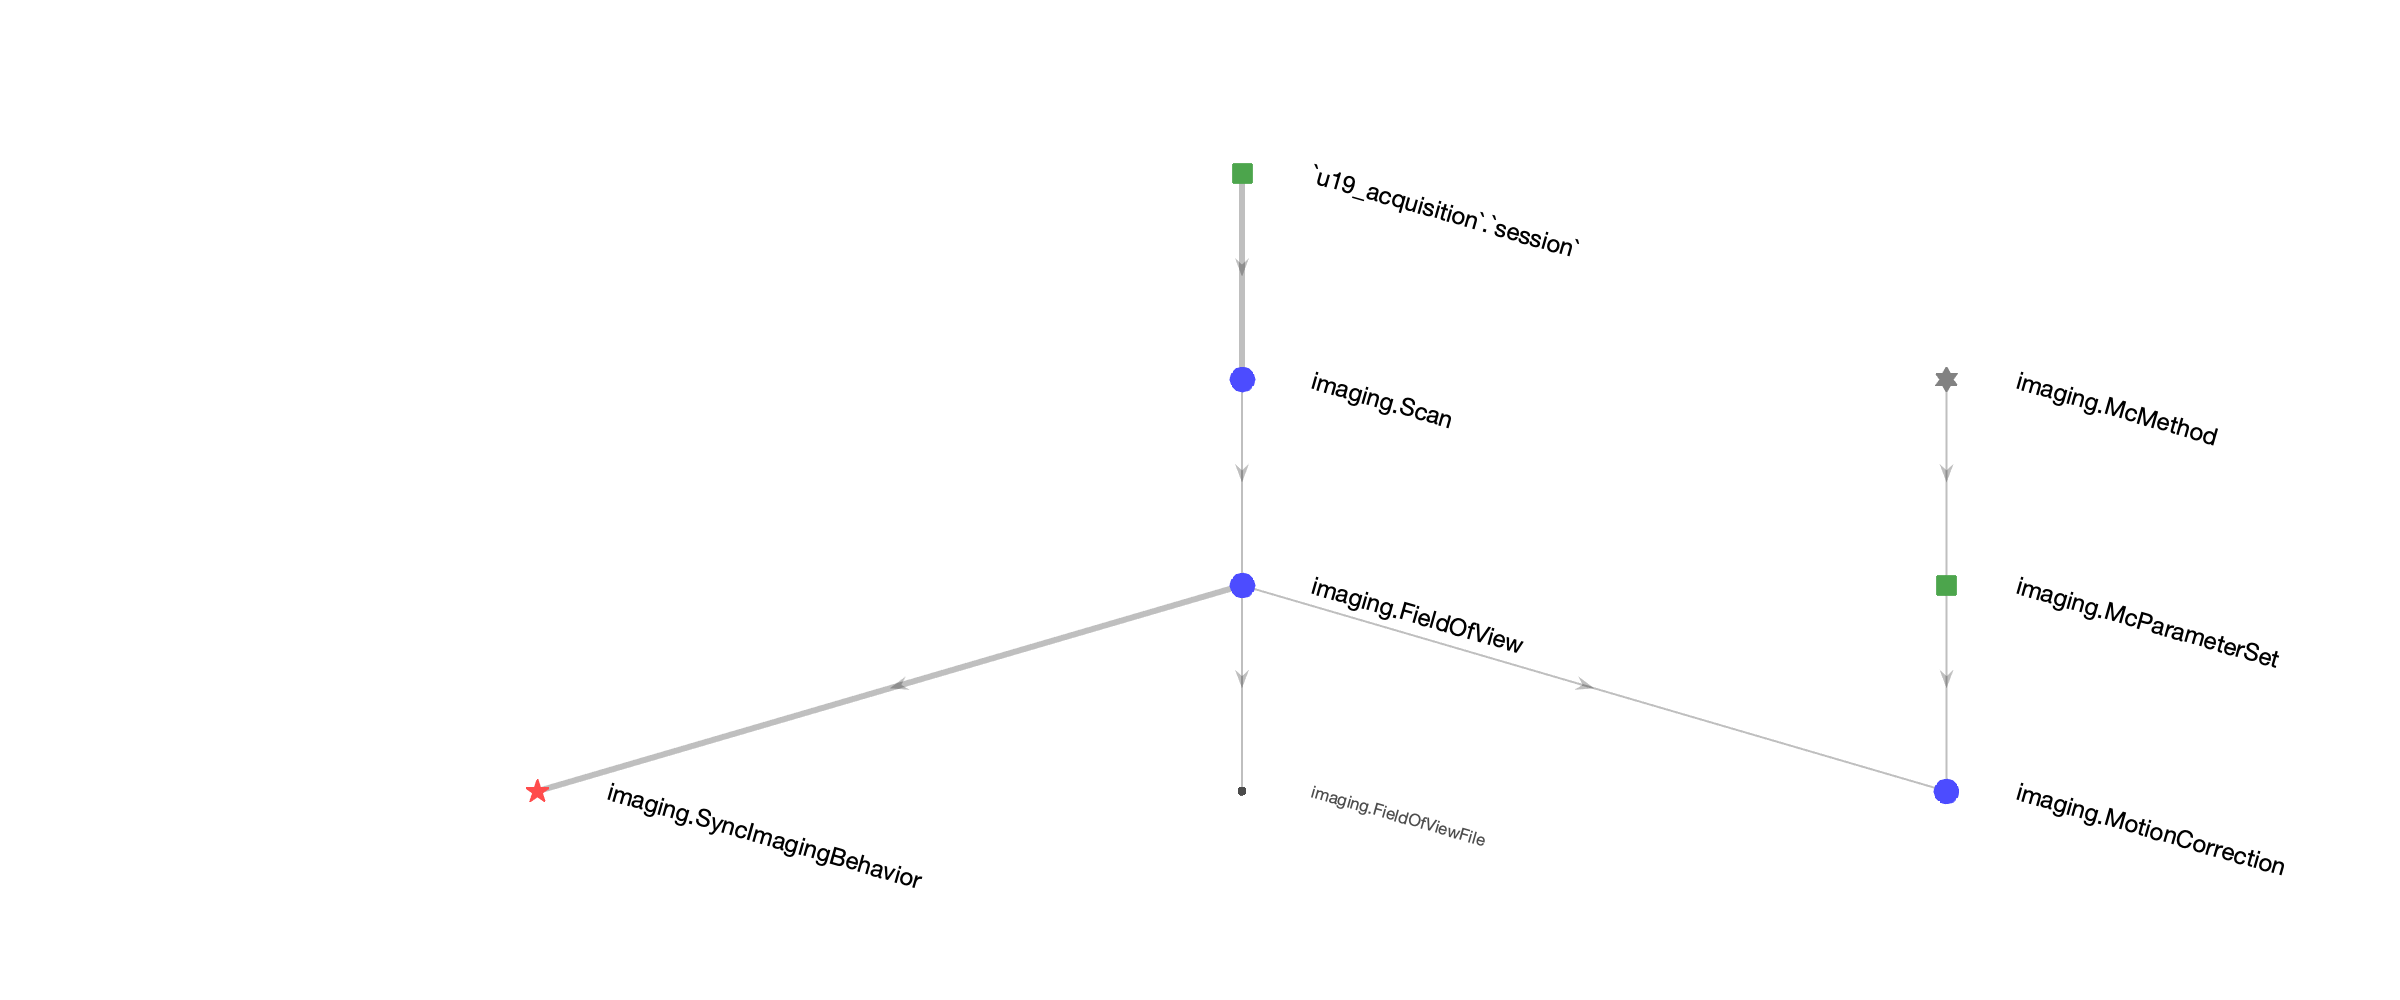

figure
set(gcf,'position',[0,0,1200,500])
erd(imaging.FieldOfView)

We created an example session for the tutorial:

**subject_fullname**: testuser_imaging_pipe1 **session_date**: 2021-03-01

Check if Session is present on acquisition session

session_key = struct();
session_key.subject_fullname = 'testuser_imaging_pipe1';
session_key.session_date     = '2021-03-01';
session_data = fetch(acquisition.Session & key, '*')

session_data = struct with fields:
        subject_fullname: 'testuser_imaging_pipe1'
            session_date: '2021-03-01'
          session_number: 0
      session_start_time: '2021-03-01 15:39:00'
        session_end_time: '2021-03-01 17:13:00'
        session_location: 'Bezos3'
                    task: 'Towers'
                   level: 11
                  set_id: 1
           stimulus_bank: 'C:/Experiments/ViRMEn/experiments/protocols/stimulus_trains_PoissonBlocksCondensed3m_20sets_dup0p5_pan100_n400_x10.mat'
         stimulus_commit: 'c782eb3f7737c2672c66c1b4405e3be569e80db4'
     session_performance: 71.9723
              num_trials: 289
          num_trials_try: 289
       session_narrative: ''
        session_protocol: 'poisson_blocks.m poisson_blocks_reboot_3m.mat PoissonBlocksCondensed3m'
    session_code_version: {[2.1000]  [4]}
          is_bad_session: 0
        session_comments: ''


#### Check Imaging path

Imaging (tiff) files stored must be presnt on the **imaging_bucket_default_path** according to acquisition location.

In this case the expected path is: **/mnt/bucket/Bezos/RigData/scope/bay3/testuser/imaging_pipe1/20210301/**

location_key.location = session_data.session_location;
fetch(lab.Location & location_key, '*')

ans = struct with fields:
                       location: 'Bezos3'
               acquisition_type: '2photon'
           location_description: ''
            bucket_default_path: '/braininit/RigData/scope/bay3/'
    imaging_bucket_default_path: '/Bezos/RigData/scope/bay3/'


#### Populate Scan table

populate(imaging.Scan & session_key);

imaging.Scan: Nothing to populate


fetch(imaging.Scan & session_key, '*')

ans = struct with fields:
    subject_fullname: 'testuser_imaging_pipe1'
        session_date: '2021-03-01'
      session_number: 0
      scan_directory: '/mnt/bucket/PNI-centers/Bezos/RigData/scope/bay3/testuser/imaging/testuser_imaging_pipe1/20210301'


#### Populate ScanInfo, FieldOfView & FieldOfViewFile table

populate(imaging.ScanInfo, session_key)


**imaging.ScanInfo: Found 1 unpopulated keys

Populating imaging.ScanInfo for:
    subject_fullname: 'testuser_imaging_pipe1'
        session_date: '2021-03-01'
      session_number: 0

------------ preparing /Volumes/Bezos-center/RigData/scope/bay3/testuser/imaging/testuser_imaging_pipe1/20210301 --------------


Index exceeds the number of array elements (0).

Error in imaging.ScanInfo/check_tif_files (line 163)
            stridx   = regexp(fl{1},self.tif_number_fmt);

Error in imaging.ScanInfo/makeTuples (

% restrictor as a string, unequal
subject.Subject & 'dob > "2019-01-01"'

% restrictor as a string, within a range
subject.Subject & 'dob between "2019-01-01" and "2019-02-01"'

% restrictor as a string, "or" 
subject.Subject & 'sex in ("Male", "Female")'

% restrictor as a string, "or" 
subject.Subject & 'sex = "Male" or sex = "Female"'

For more syntax of restrictors as a string, check on MYSQL syntax. DataJoint supports most of the MYSQL syntax.

DataJoint also takes a struct as a restrictor:

subject.Subject & struct('user_id', 'lpinto', 'sex', 'Male')

Retrictor as a array of struct perform the 'or' logic.

subject.Subject & [struct('user_id', 'lpinto', 'sex', 'Male'), struct('user_id', 'hnieh', 'sex', 'Male')]

Restrict with other tables.

All mice that have a session

subject.Subject & acquisition.Session

All mice that don't have a session

subject.Subject - acquisition.Session

All forms of restrictors could be combined:

subject.Subject & [struct('user_id', 'koay', 'sex', 'Male'), struct('user_id', 'hneih', 'sex', 'Male')] & 'subject_nickname="K62"'

### Join `*` gathers fields from different tables together

subject.Subject * action.WaterAdministration

### Projection `proj(`) only keeps a subset of the secondary attributes

No arguments:

% with no arguments it only keeps the primary key
subject.Subject().proj()

It also works like this.

proj(subject.Subject)

Actually this is more commonly used because adding filters to this is easy.

proj(subject.Subject & 'user_id="lpinto"')

Now keep some other attributes as well:

proj(subject.Subject, 'dob', 'sex')

`proj()` also allows renaming the fields

proj(subject.Subject, 'dob->birth_date', 'sex')

and some simple computations:

Example 1: get the date of a weighing

proj(action.Weighing & 'subject_id="B205"', 'date(weighing_time)->weighing_date')

Example 2: What is the age of an animal when performing each session?

% First get the date of birth and the session date into the same query
q = subject.Subject().proj('dob') * acquisition.Session().proj() & 'dob != ""'

% Then perform the computation with proj()
q.proj('datediff(session_date, dob)->age_in_days')

 Aggregation `.aggr()`: simple computation of one table against another table

Example: how many animals does each user have?

lab.User().aggr(subject.Subject, 'count(*)->n_animals')

## Fetching data

So far, we have been querying from the database, but did not get any data fetched, in the form of matlab data types. We could fetch from **any query** we performed so far. With the syntax `fetch(query, ...)` or `query.fetch(...)`

Fetch everything from a table: get an structure array of primary keys

subject.Subject().fetch()

Fetch all fields, but still as an array of struct

subjects_stats = fetch(subject.Subject, 'sex', 'dob')

Everything you get with `fetch()` is an array of sturct, with the primary keys, even if you only have one entry. If you want other data formats to return without the primary key, here are two other options:

- fetch1(): works on queries only with one entry

- fetchn(): works on any queries

fetch1(subject.Subject & 'subject_nickname="E70"', 'initial_weight')

fetchn(subject.Subject & 'subject_nickname="E70"', 'initial_weight')

fetchn(subject.Subject, 'dob')

Fetch multiple fields at the same time, individually

[dob, sex, initial_weight] = fetch1(subject.Subject & 'subject_nickname="E74"', 'dob', 'sex', 'initial_weight')

subj = subject.Subject & 'subject_nickname="E74"'
subj_key = subj.fetch()
[water_date, earned_water] = fetchn(action.WaterAdministration & subj_key, 'administration_date', 'earned');

Earned water as a function of date.

water_date = datetime(water_date);
figure; plot(water_date, earned_water, 'ko-')
ylim([0, 1.5])

Weight as a function of date.

[weighing_date, weight] = fetchn(...
    action.Weighing & subj_key, 'DATE(weighing_time)->weighing_date', 'weight');
weighing_date = datetime(weighing_date);
figure; plot(weighing_date, weight, '.-')

Plot both together:

figure; hold on
yyaxis left
plot(weighing_date, weight, '.-')
yyaxis right
plot(water_date, earned_water, '.-')

Performance as a function of date

acquisition.Session

acquisition.Session & subj_key

Plot performance as a function of date.

[session_date, performance] = fetchn(acquisition.Session & subj_key, 'session_date', 'session_performance');
session_date = datetime(session_date);
figure; plot(session_date, performance, '.-')

Plot both performance and earned water as a function of date.

figure; hold on
yyaxis left
plot(session_date, performance, '.-')
yyaxis right
plot(water_date, earned_water, '.-')

Compute trial numbers of a given date.

behavior.TowersBlockTrial & subj & 'session_date="2018-09-20"'

Compute trial numbers of each date

query = acquisition.Session & subj_key
[session_date, n_trials] = fetchn(query.aggr(behavior.TowersBlockTrial, 'count(*) -> n'), 'session_date', 'n');
session_date = datetime(session_date);
figure; hold on
yyaxis left
plot(session_date, performance, '.-')
yyaxis right
plot(water_date, earned_water, '.-')

## Summary

In session 1, we have covered basic methods to explore, browse and fetch data from the data pipeline. In the next session, we will learn how to generate different kinds of tables, ingest, delete, and compute entries.